# System Identification (MPC)

## 1. Load + format data

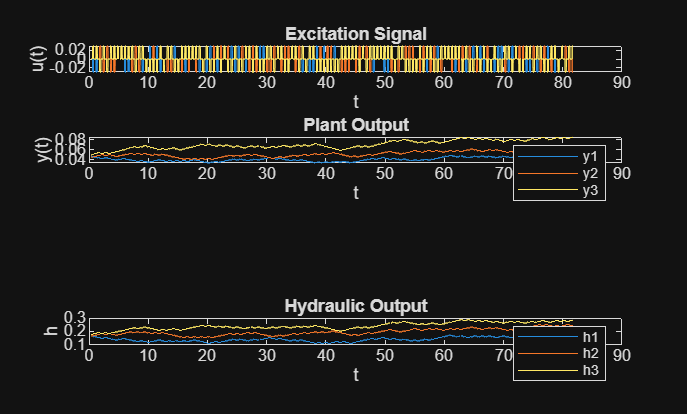

data_path_est = fullfile("data", "noise-free", "IdMPC_est.mat");
data_path_val = fullfile("data", "noise-free", "IdMPC_val.mat");
Ts = 0.02;
load(data_path_est);
% Drop the first sample
startIdx = 20;
t = t(startIdx:end, :);
u = u(startIdx:end, :);
y = y(startIdx:end, :);
% y_real = y_real(startIdx:end, :);
l_hy = l_hy(startIdx:end, :);

figure;
subplot(4, 1, 1);
plot(t, u);
title('Excitation Signal'); xlabel('t'); ylabel('u(t)');
subplot(4, 1, 2);
plot(t, y);
title('Plant Output'); xlabel('t'); ylabel('y(t)');
legend("y1", "y2", "y3");
% subplot(4, 1, 3);
% plot(t, y_real);
% title('Plant Output (Noise-free)'); xlabel('t'); ylabel('y(t)');
% legend("y1", "y2", "y3");
subplot(4, 1, 4);
plot(t, l_hy);
title('Hydraulic Output'); xlabel('t'); ylabel('h');
legend("h1", "h2", "h3");

## 2. Create `iddata` + detrend

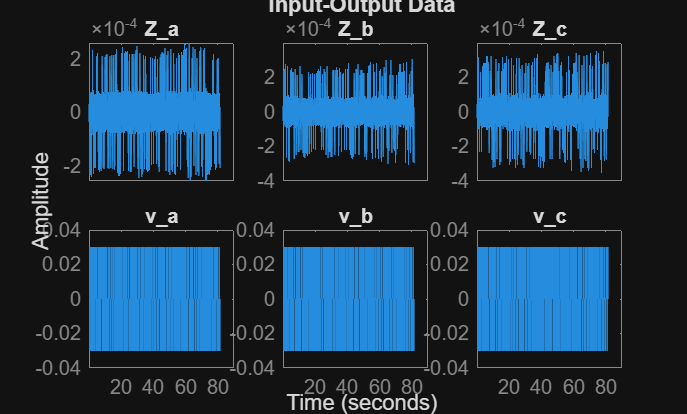

y = diff(y);
u = diff(u);

data = iddata(y, u, Ts, "TimeUnit", "s");
data.InputName = {"v_a", "v_b", "v_c"};
data.OutputName = {"Z_a", "Z_b", "Z_c"};

% remove mean
% data = detrend(data, 0);

figure;
idplot(data);

## 3. Split estimation/validation

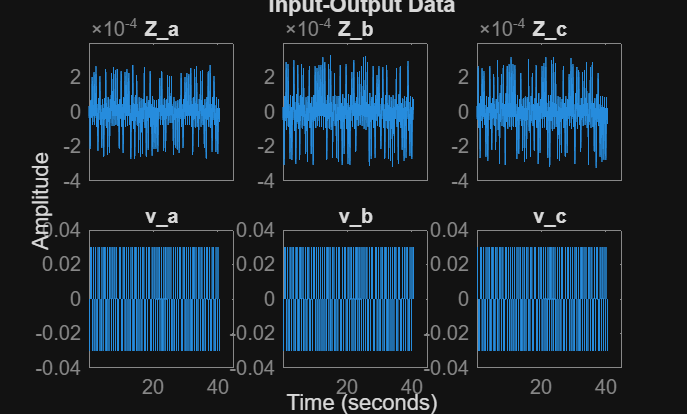

% N = size(data.OutputData, 1);
% Ne = floor(0.7*N);
% 
% data_est = data(1:Ne);
% data_val = data(Ne+1:end);

data_est = data;
load(data_path_val);
t = t(startIdx:end, :);
u = u(startIdx:end, :);
y = y(startIdx:end, :);
% y = y_real(startIdx:end, :);
l_hy = l_hy(startIdx:end, :);

u = diff(u);
y = diff(y);

data_val = iddata(y, u, Ts, "TimeUnit", "s");
data_val.InputName = {"v_a", "v_b", "v_c"};
data_val.OutputName = {"Z_a", "Z_b", "Z_c"};
figure;
idplot(data_val);

## 4. Estimate state-space order by scanning (n4sid -> ssest refine)

orders = 2:15;
% orders = 9;

optN4 = n4sidOptions( ...
    'Focus','simulation', ...
    'N4Weight','CVA');

optSS = ssestOptions( ...
    'Focus','simulation', ...
    'EnforceStability', false);   % allow poles near z=1

optCO = compareOptions("InitialCondition", "estimate");

bestFit = -Inf;
bestSys = [];

for nx = orders
    sys0 = n4sid(data_est, nx, optN4);      % subspace initial model
    % sys  = ssest(data_est, sys0, optSS);    % PEM refinement (usually improves fit)
    sys = sys0;

    [~, fit] = compare(data_val, sys, optCO);      % fit is 1×3 (%)
    meanFit = mean(fit);

    fprintf('nx=%d, fit=[%.1f %.1f %.1f], mean=%.1f\n', nx, fit, meanFit);

    if meanFit > bestFit
        bestFit = meanFit;
        bestSys = sys;
    end
end

nx=2, fit=[-0.0 0.5 0.6], mean=0.4
nx=3, fit=[2.3 1.4 1.8], mean=1.8
nx=4, fit=[5.1 14.5 17.8], mean=12.5
nx=5, fit=[12.8 33.6 7.8], mean=18.0
nx=6, fit=[18.1 18.2 17.1], mean=17.8
nx=7, fit=[10.0 37.9 57.9], mean=35.3
nx=8, fit=[36.5 47.6 64.0], mean=49.4
nx=9, fit=[71.3 74.5 74.5], mean=73.4
nx=10, fit=[77.6 76.9 83.3], mean=79.3
nx=11, fit=[90.7 81.8 87.6], mean=86.7
nx=12, fit=[91.2 90.5 96.4], mean=92.7
nx=13, fit=[91.1 90.7 96.4], mean=92.7
nx=14, fit=[91.3 90.8 96.3], mean=92.8
nx=15, fit=[83.8 69.0 83.7], mean=78.8



bestSys


bestSys =
  Discrete-time identified state-space model:
    x(t+Ts) = A x(t) + B u(t) + K e(t)
       y(t) = C x(t) + D u(t) + e(t)
 
  A = 
                x1          x2          x3          x4          x5          x6          x7          x8          x9         x10         x11         x12         x13         x14
   x1       0.8858      0.3884    -0.09499   -0.005037   0.0003354    -0.01654   -0.003611   -0.004469   0.0003115   0.0001592   0.0005827  -0.0004529     0.00219     0.00366
   x2      -0.3958      0.7919      0.3326   -0.008674    0.003979     -0.0257   -0.006521  -0.0001699    0.007091   -0.001037    0.000252  -0.0001804   -0.003186   -0.004617
   x3     -0.07647     -0.4063   -0.004722     0.04628    -0.01412   -0.001075   -0.001635   -0.003887     0.00838   0.0005861    0.002127   -0.003007     0.01972     0.03953
   x4      0.00865    0.001983     0.02957      0.8756      0.3725     -0.1031    -0.00744   -0.002545     0.01238  -0.0008675    0.001378   0.0003479     0.0

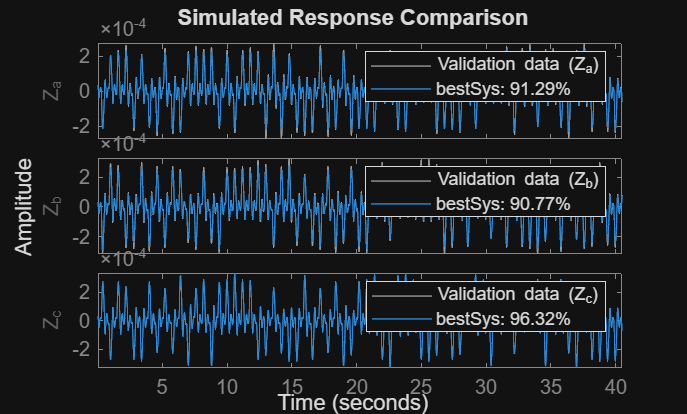

figure;
compare(data_val, bestSys, optCO);

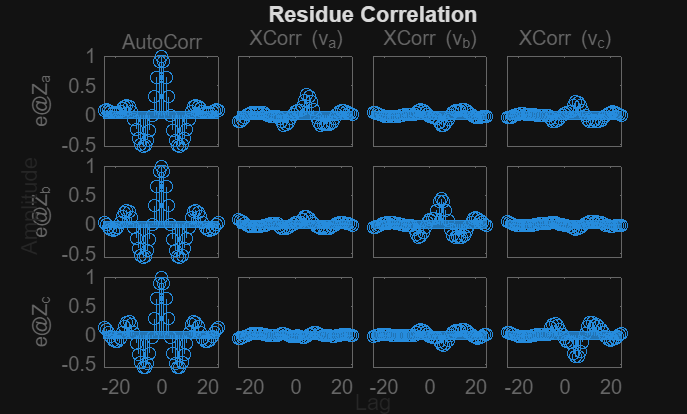

figure;
resid(data_val, bestSys);

eig(bestSys.A)   % expect at least one eigenvalue near 1

ans =    0.0485 + 0.0000i
   0.0958 + 0.0000i
   0.1181 + 0.0000i
   0.8709 + 0.4125i
   0.8709 - 0.4125i
   0.7862 + 0.4399i
   0.7862 - 0.4399i
   0.7867 + 0.4407i
   0.7867 - 0.4407i
   0.7868 + 0.4400i
   0.7868 - 0.4400i
   0.9999 + 0.0000i
   1.0000 + 0.0001i
   1.0000 - 0.0001i


## 5. Validate the model

%% --- Convert the incremental model to a standard model ---
[A,B,C,D] = ssdata(bestSys);

nx = size(A,1);
ny = size(C,1);
nu = size(B,2);

Iy = eye(ny);
Iu = eye(nu);

Aaug = [ A,          zeros(nx,ny),   -B;
         C,          Iy,             -D;
         zeros(nu,nx), zeros(nu,ny), zeros(nu,nu) ];

Baug = [ B;
         D;
         Iu ];

Caug = [ C, Iy, -D ];
Daug = D;

bestSys = ss(Aaug, Baug, Caug, Daug, Ts);   % input=u, output=y

load(data_path_val, "t", "u", "y");
t = t(startIdx:end, :);
u = u(startIdx:end, :);
y = y(startIdx:end, :);
% y = y_real(startIdx:end, :);
data_val = iddata(y, u, Ts, "TimeUnit", "s");
figure;
compare(data_val, bestSys, optCO);


% %% --- Kalman state estimator for incremental model (du -> dy) ---
% % data_val: iddata with Output=dy, Input=du
% du = data_val.InputData;     % [N x nu]
% dy = data_val.OutputData;    % [N x ny]
% N  = size(dy,1);
% 
% % Extract state-space matrices
% [A,B,C,D] = ssdata(bestSys);
% 
% % Get Kalman gain from identified innovation model (idss)
% if ~isempty(bestSys.K)
%     K = bestSys.K;
% else
%     error("bestSys has no Kalman gain K. Make sure bestSys is an idss (innovation form).");
% end
% 
% nx = size(A,1);
% ny = size(C,1);
% 
% % Initial state (required): x0 = 0
% xhat = zeros(nx,1);
% 
% % Allocate
% dy_hat = zeros(N, ny);
% 
% % Kalman filter recursion (innovation form):
% %   e(k)     = dy(k) - (C x(k) + D du(k))
% %   x(k+1)   = A x(k) + B du(k) + K e(k)
% for k = 1:N
%     uk = du(k,:).';                 % [nu x 1]
%     yk = dy(k,:).';                 % [ny x 1]
% 
%     y_pred = C*xhat + D*uk;         % dy one-step-ahead prediction
%     dy_hat(k,:) = y_pred.';         % store
% 
%     e = yk - y_pred;                % innovation
%     xhat = A*xhat + B*uk + K*e;     % state update
% end
% 
% %% --- Reconstruct y_hat using measured initial y as anchor ---
% data_path = fullfile("data", "IdMPC_val.mat");
% load(data_path, "y_real");               % y is the ORIGINAL (non-incremental) output
% 
% y0 = y_real(startIdx, :);
% y_hat = y0 + cumsum(dy_hat, 1);
% 
% % Safer indexing (avoid length mismatch)
% idx = startIdx + (1:N);             % corresponds to y(k) for k=startIdx+1...startIdx+N
% 
% %% --- Plot y vs y_hat ---
% figure;
% for i = 1:3
%     subplot(3,1,i);
%     plot(y_real(idx, i)); hold on;
%     plot(y_hat(:, i)); hold off;
%     grid on;
%     legend("y", "y_hat");
% end

## 6. MPC implementation

plant = ss(bestSys);
max(abs(eig(plant.A)))  % No eigenvalue noticeably > 1

p = 40;  % prediction horizon
m = 10;  % control horizon

mpcobj = mpc(plant, Ts, p, m);  % create the MPC object
setname(mpcobj, "input", 1, "v_a");
setname(mpcobj, "input", 2, "v_b");
setname(mpcobj, "input", 3, "v_c");
setname(mpcobj, "output", 1, "Z_a");
setname(mpcobj, "output", 2, "Z_b");
setname(mpcobj, "output", 3, "Z_c");

% Put in constraints
v_max = 0.1579; v_min = -0.3612;  % speed range of electrodes
for i = 1 : 3
    mpcobj.MV(i).Min = v_min;
    mpcobj.MV(i).Max = v_max;
end

mpcobj.Weights.OutputVariables = [1 1 1];              % track impedance
mpcobj.Weights.ManipulatedVariables = [0 0 0];         % usually small/zero
mpcobj.Weights.ManipulatedVariablesRate = [0.1 0.1 0.1]; % smooth velocity moves
mpcobj.Weights.ECR = 1e5;                               % penalty for constraint softening

% % Create the output disturbance model
% integrator = tf(1, [1 -0.95], Ts);
% outdist = blkdiag(integrator, integrator, integrator);
% setoutdist(mpcobj, 'model', outdist);
% 
% xc = mpcstate(mpcobj);
% [numel(xc.Plant) numel(xc.Disturbance) numel(xc.Noise)]

mpcobj